clc;
clear all;
close all;

addpath(genpath("../../methods"));% inport metods
addpath(genpath("../EA1"));% inport folder with code

Initial Parametr

pt1

%nominal parameters
r_nom = 0.03;
d_nom = 0.165;
omega_max = 10;
w_max=10;

%time
Ts = 0.04;
Ta = 1;
Tc = 30;
total_time = 2*Ta + Tc;
t = 0:Ts:total_time;

%trajectory
R = 0.4;
omega_trj = 2*pi;

pt2

load(fullfile("EA1/robot laboratory/measurements/", 'Tc_30.mat'));%load measure data
Q_INIT      = sim_Tc_30.measures.signals.values(1,1:3)';                % Initial pose
PHI_INIT    = [0; 0];                   % Initial wheels angles
Q_INIT_LOC  = sim_Tc_30.measures.signals.values(1,1:3)';                % Initial pose for localization
Z_INIT_EKF  = [sim_Tc_30.measures.signals.values(1,1:3)'; 0; 0; 0; 0];    % Initial EKF state vector

%k = 0                  % 0 = forward, 1 = backwards

flag_GPS = 1;           % 0 = GPS OFF, 1 = GPS ON
prob_gps_loss = 0.99;    % 0.0 to 1.0 loss probability for GPS where 0 = no loss; defined p_loss in note
ENCODER_QUANTIZATION = 1;

% EKF initial covariance
P_INIT_EKF = diag([0.001, 0.001, 0.0175/6, 0.0175/6, 0.0175/6, 0.0175/6*Ts, 0.0175/6*Ts].^2);

% EKF process noice covariance
D = diag([0.001, 0.001, 0.0175/6, 0.0175/6, 0.0175/6, 0.0175/6*Ts, 0.0175/6*Ts].^2);

% EKF measurement noise
R_2 = diag([ENCODER_QUANTIZATION/6,ENCODER_QUANTIZATION/6].^2);                         %(delta wheels angles)
R_3 = diag(([0.001, ENCODER_QUANTIZATION/6,ENCODER_QUANTIZATION/6]).^2);                %(GPS(1 value) + delta wheels angles)
R_4 = diag(([0.001, 0.001, ENCODER_QUANTIZATION/6,ENCODER_QUANTIZATION/6]).^2);         %(GPS(2 values) + delta wheels angles)
R_5 = diag(([0.001, 0.001, 0.001, ENCODER_QUANTIZATION/6,ENCODER_QUANTIZATION/6]).^2);  %(GPS(3 values) + delta wheels angles)

%prepare data for function
q4id = sim_Tc_30.measures.signals.values(:,1:3);
q4id(:,3) = unwrap(q4id(:,3));
omega_wheels=[sim_Tc_30.measures.signals.values(:,5),sim_Tc_30.measures.signals.values(:,4)];

Pt3

diff_flatness = 0;      % choice of input interpretation (0:cartesian, 1:chained form)
reorientation = 0;      % in case of chained form, choice of a translation (0:no translation, 1:translation) 

q_i = [-0.5, -0.5, pi/2];
q_f = [ 0.5,  0.5, pi/2];
k_i = 10;
k_f = 10; 
k_sign = sign(k_i);

Part 1

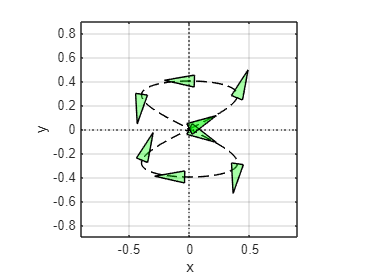

%trajectory
x=@(s) R*sin(2*omega_trj.*s);
y=@(s) R*sin(omega_trj.*s);

%trajectory analitic derivatives
x_dot =@(s) R*2*omega_trj*cos(2*omega_trj*s);
y_dot =@(s) R*omega_trj*cos(omega_trj*s);

x_ddot =@(s) R*4*omega_trj*omega_trj*(-sin(2*omega_trj*s));
y_ddot =@(s) R*omega_trj*omega_trj*(-sin(omega_trj*s));

%timelaw
mode = 2;           
[s, s_dot] = time_law_fn(t,total_time,mode,Ta,Tc);

%calculate q_d [x;y;theta] and u [v;w] and prepare it for the sim
[q_d, u] = cartesian_output_2_kin_stateInput(x(s),y(s),x_dot(s),y_dot(s),x_ddot(s),y_ddot(s),s_dot);
q_d_sim=timeseries(q_d',t);
u_sim=timeseries(u',t);%initial value problems

% Plot the trajectory
plot_unicycle_2D(q_d, 100)

1.8 simulation and data acquisition

%comment when we not want to take measure
% Tc=30;
% total_time = 2*Ta + Tc;
% t = 0:Ts:total_time;
% %timelaw
% mode = 2;           
% [s, s_dot] = time_law_fn(t,total_time,mode,Ta,Tc);
% out = sim('Final_sim.slx');
% sim_Tc_30=out;
% 
% 
% Tc=18;
% total_time = 2*Ta + Tc;
% t = 0:Ts:total_time;
% %timelaw
% mode = 2;           
% [s, s_dot] = time_law_fn(t,total_time,mode,Ta,Tc);
% out = sim('Final_sim.slx');
% sim_Tc_18=out;
% 
% 
% Tc=45;
% total_time = 2*Ta + Tc;
% t = 0:Ts:total_time;
%timelaw
% mode = 2;           
% [s, s_dot] = time_law_fn(t,total_time,mode,Ta,Tc);
% out = sim('Final_sim.slx');
% sim_Tc_45=out;

Part2

identification and calibration (2.1)

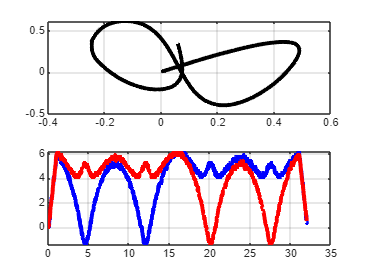

%run("id_template.m") % trasforma in funzione (ha un clear all?)
%plot measuraments
figure()
subplot(2,1,1)
plot(q4id(:,2), q4id(:,1), 'LineWidth', 3, 'Color','k')
grid on;
subplot(2,1,2)
plot(t(2:end), omega_wheels(2:end,1), 'LineWidth', 3, 'Color','b')
hold on
plot(t(2:end), omega_wheels(2:end,2), 'LineWidth', 3, 'Color','r')
grid on;


Minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>


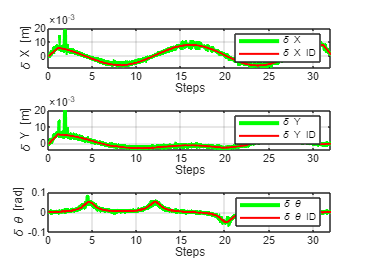


%evaluate stime without calibration

hat=id_cal_fun(q4id,omega_wheels,Ts,t,0);

r_unconstrained_hat=hat(1);
d_unconstrained_hat=hat(2);


fprintf('Uncalibrated estimates:\n');

Uncalibrated estimates:


fprintf('r = %.4f [m]\n', r_unconstrained_hat);

r = 0.0326 [m]


fprintf('d = %.4f [m]\n\n', d_unconstrained_hat);

d = 0.1690 [m]




Minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>

Minimum found that satisfies the constraints.

Optimization completed because

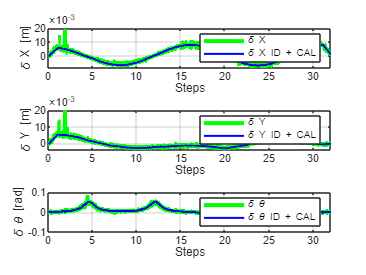



%evaluate stime with calibration
hat=id_cal_fun(q4id,omega_wheels,Ts,t,1);

r_cal_hat=hat(1);
d_cal_hat=hat(2);
x_off_cal_hat=hat(3);
y_off_cal_hat=hat(4);
offset_hat=hat(5);

fprintf('Calibrated estimates:\n');

Calibrated estimates:


fprintf('r = %.4f [m]\n', r_cal_hat);

r = 0.0326 [m]


fprintf('d = %.4f [m]\n', d_cal_hat);

d = 0.1690 [m]


fprintf('x offset = %.4f [m]\n', x_off_cal_hat);

x offset = 0.0000 [m]


fprintf('y offset = %.4f [m]\n', y_off_cal_hat);

y offset = 0.0004 [m]


fprintf('Orientation offset = %.4f [rad]\n', offset_hat);

Orientation offset = 0.0153 [rad]


Test Locatization strategies (integration and EFK) by simulating collected data (2.2)

%plot values?
%manca integration?

Pt3

if (diff_flatness == 0)
    y = planTrajectoryCartesianPolynomials(q_i, q_f, k_i, k_f);
else 
    y = planTrajectoryChainedForm(q_i, q_f, reorientation);
end